## PART 1: KINEMATICS

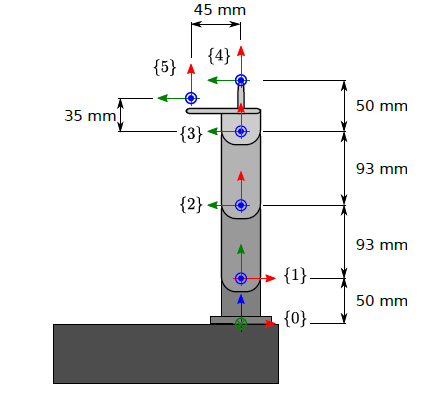

addpath('./src');

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% from DH convention we get:

% {0} -> {1}
T01 = [cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1];

% {1} -> {2}
T12 = [cos(theta1), -sin(theta1), 0, L12*cos(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {2} -> {3}
T23 = [cos(theta2), -sin(theta2), 0, L23*cos(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {4}     
T34 = [cos(theta3), -sin(theta3), 0, L34*cos(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {5}
T35 = [1, 0, 0, L35;
       0, 1, 0, L45;
       0, 0, 1, 0;
       0, 0, 0, 1];

% Transformation from {0} to {4}
T04 = simplify(T01*T12*T23*T34)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0}\right) & -\sigma_{1}\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{0}\right) & -\sigma_{1}\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & 50\,\sigma_{1}+93\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = simplify(T01*T12*T23*T35)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{1}\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{1}\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & 93\,\sin\left(\theta_{1}\right)+\sqrt{18409}\,\cos\left(\theta_{1}+\theta_{2}-\mathrm{atan}\left(\frac{128}{45}\right)\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=128\,\cos\left(\theta_{1}+\theta_{2}\right)-45\,\sin\left(\theta_{1}+\theta_{2}\right)+93\,\cos\left(\theta_{1}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

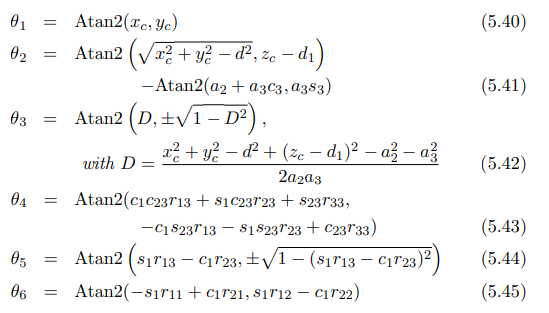

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





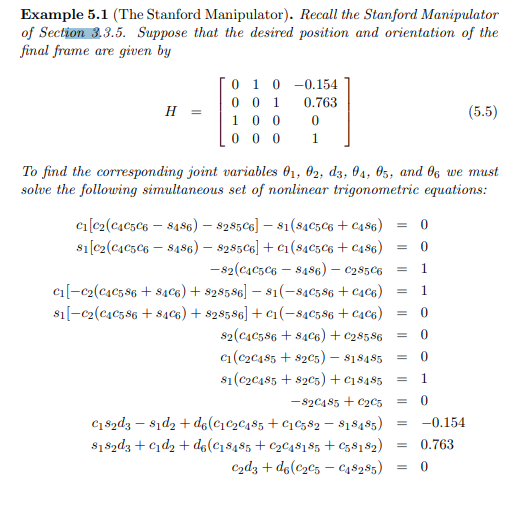

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

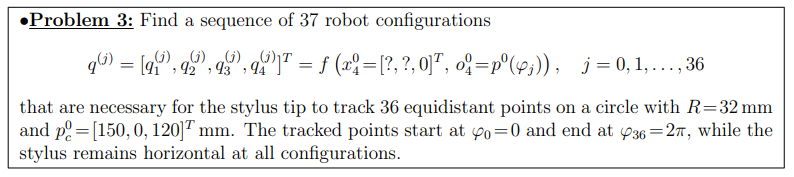

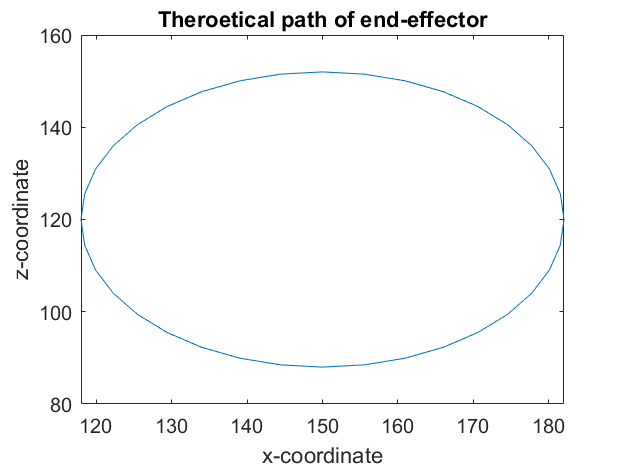


% origin of the circle to be traced
xc = 150;
yc = 0;
zc = 120;

angles = 0:2*pi/36:2*pi; % this is the phi angle reported in the previous line


dx = cos(angles)*32;
dz = sin(angles)*32;

x = xc + dx;
y = yc*ones(1,length(angles));
z = zc + dz;

figure
plot(x,z)
title("Theroetical path of end-effector")
xlabel("x-coordinate")
ylabel("z-coordinate")



% transform coordinates to angles
% Stylus always parallel to the ground
x04 = [1, 0, 0];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

Angles:
 theta1: 
     0

 theta2: 
   -0.7373

 theta3: 
   79.9252

 theta4: 
  -79.1879

Angles:
 theta1: 
     0

 theta2: 
   -0.9089

 theta3: 
   79.5043

 theta4: 
  -78.5954

Angles:
 theta1: 
     0

 theta2: 
   -0.7468

 theta3: 
   79.7508

 theta4: 
  -79.0041

Angles:
 theta1: 
     0

 theta2: 
   -0.2561

 theta3: 
   80.6559

 theta4: 
  -80.3998

Angles:
 theta1: 
     0

 theta2: 
    0.5465

 theta3: 
   82.1871

 theta4: 
  -82.7336

Angles:
 theta1: 
     0

 theta2: 
    1.6341

 theta3: 
   84.2922

 theta4: 
  -85.9263

Angles:
 theta1: 
     0

 theta2: 
   -0.1696

 theta3: 
   86.9031

 theta4: 
  -86.7335

Angles:
 theta1: 
     0

 theta2: 
    1.3787

 theta3: 
   89.9413

 theta4: 
  -91.3199

Angles:
 theta1: 
     0

 theta2: 
   -0.0480

 theta3: 
   93.3211

 theta4: 
  -93.2731

Angles:
 theta1: 
     0

 theta2: 
    1.7879

 theta3: 
   96.9530

 theta4: 
  -98.7409

Angles:
 theta1: 
     0

 theta2: 
    0.5558

 theta3: 
  100.7443

 theta4: 



pos2 = zeros(4,37);
for i = 1:size(pos,2)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    T04 = T01*T12*T23*T34;
    pos2(:,i) = T04*[0,0,0,1]';
end
pos2

pos2 =    44.6984   14.3042   35.0953  166.4916  175.5499    2.2059  172.6585  -23.1258  195.1078    9.7352  195.8196   34.4502  -10.6057  188.5983  -12.2008  207.5347  -11.5701   15.4040  127.8917  193.9805  144.1746    5.8174    0.0021  234.6180   38.0648  233.1695    9.8143   88.9885  116.0063    5.1817  235.6994   23.0569  225.2291   40.1130  128.3963  196.5210   44.6984
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -68.6640  -28.5266  -54.8134  -62.6920  179.1039   59.7950  -53.3792  121.5621  -31.4177   50.0430  163.7568  -31.6776  164.1891  -36.2613   68.7130  -17.7779  149.6996    6.1909  -78.6050  -45.7113  -80.4882  -28.7930  100.4671   28.2959   49.4046 

pos

pos =   182.0000  181.5138  180.0702  177.7128  174.5134  170.5692  166.0000  160.9446  155.5567  150.0000  144.4433  139.0554  134.0000  129.4308  125.4866  122.2872  119.9298  118.4862  118.0000  118.4862  119.9298  122.2872  125.4866  129.4308  134.0000  139.0554  144.4433  150.0000  155.5567  160.9446  166.0000  170.5692  174.5134  177.7128  180.0702  181.5138  182.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  120.0000  125.5567  130.9446  136.0000  140.5692  144.5134  147.7128  150.0702  151.5138  152.0000  151.5138  150.0702  147.7128  144.5134  140.5692  136.0000  130.9446  125.5567  120.0000  114.4433  109.0554  104.0000   99.4308   95.4866   92.2872  

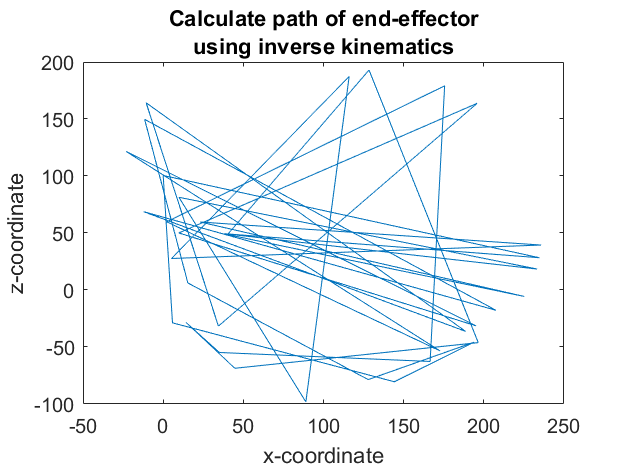


figure
plot(pos2(1,:),pos2(3,:))
title(["Calculate path of end-effector", "using inverse kinematics"])
xlabel("x-coordinate")
ylabel("z-coordinate")



%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


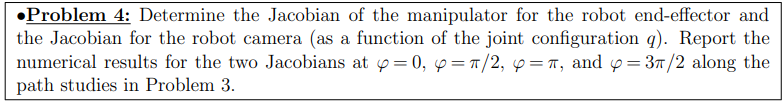

% if you need help figuring out the angles contact Palli
clc

phi = [0 pi/2 pi 3*pi/2];

dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);

Error using atan2
Inputs must be real.

Error in theta (line 11)
t3 = atan2(D, sqrt(1-D.^2));

t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end


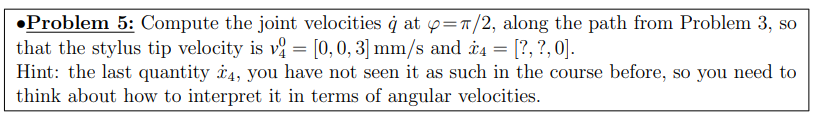

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:3%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34
    T03=T01*T12*T23
    T02=T01*T12
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1*(1/max(k1));
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2*(1/max(k2));
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3*(1/max(k3));
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4*(1/max(k4));

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    v04 = cross(w04,o4)
    

end

T04 =     0.0000   -0.7089    0.7053  -14.4839
    0.0000   -0.7053   -0.7089  -14.4106
    1.0000    0.0000         0   78.2024
         0         0         0    1.0000


T03 =    -0.5884   -0.3954    0.7053  -14.4839
   -0.5854   -0.3934   -0.7089  -14.4106
    0.5578   -0.8300         0   28.2024
         0         0         0    1.0000


T02 =     0.4326    0.5616    0.7053   40.2343
    0.4304    0.5587   -0.7089   40.0305
   -0.7922    0.6103         0  -23.6733
         0         0         0    1.0000


v04 =    NaN   NaN   NaN


T04 =     0.0000   -0.7142    0.6999  123.8546
    0.0000   -0.6999   -0.7142  121.3648
    1.0000    0.0000         0   72.9447
         0         0         0    1.0000


T03 =     0.6294    0.3376    0.6999  123.8546
    0.6168    0.3308   -0.7142  121.3648
   -0.4727    0.8812         0   22.9447
         0         0         0    1.0000


T02 =     0.7024   -0.1298    0.6999   65.3187
    0.6882   -0.1272   -0.7142   64.0056
    0.1818    0.9833         0   66.9044
         0         0         0    1.0000


v04 =  -929.4083  948.4750    0.0000


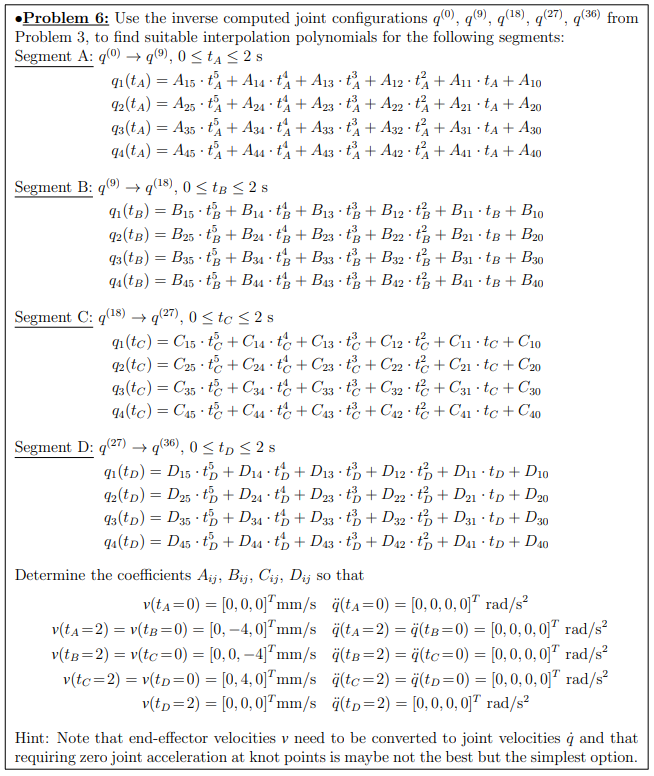

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval

V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];

q0 = [t1(1),t2(1),t3(1),t4(1)]';
qA = [t1(10),t2(10),t3(10),t4(10)]';
qB = [t1(19),t2(19),t3(19),t4(19)]';
qC = [t1(28),t2(28),t3(28),t4(28)]';
qD = [t1(37),t2(37),t3(37),t4(37)]';

%vectors of end-effffector velocities v 
[T01,T12,T23,T34,T35] = T_finder(t1(1),t2(1),t3(1),t4(1));
J0 = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(10),t2(10),t3(10),t4(10));
JA = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(19),t2(19),t3(19),t4(19));
JB = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(28),t2(28),t3(28),t4(28));
JC = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(37),t2(37),t3(37),t4(37));
JD = Jacob(T01,T12,T23,T34);

%jaconbian matrix for calculating joint velocities ˙q
q0_dot = [0, 0, 0, 0]';
qA_dot = JA'*inv(JA*JA')*VA;

qB_dot = JB'*inv(JB*JB')*VB;

qC_dot = JC'*inv(JC*JC')*VC;

qD_dot = JD'*inv(JD*JD')*VD;


%Calculation of joint velocities ˙q
ain = [0,0,0,0]';
aout = [0,0,0,0]';
%acceleration is always 0

A = getConstant(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =     0.7854    0.8279   63.5604  -62.8176
   -0.0000    0.0000    0.0000   -0.0000
         0         0         0         0
   -0.2458   -1.9358  -43.8900   45.7633
    0.1842    1.4284   32.9253  -34.2990
   -0.0368   -0.2833   -6.5858    6.8575


B = getConstant(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =     0.5880   -0.8707   28.4985  -26.0569
   -0.0010   -0.1875    0.0625    0.1875
         0         0         0         0
   -0.3314    2.4692   43.6215  -46.1844
    0.2486   -1.8365  -32.7099   34.6090
   -0.0497    0.3658    6.5414   -6.9189


C = getConstant(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =     0.3218    0.8279   63.5604  -62.8176
   -0.0000   -0.0646    0.1122   -0.0476
         0         0         0         0
    0.2547   -2.8753   10.8444   -8.0667
   -0.1813    2.1801   -8.1273    6.0326
    0.0353   -0.4384    1.6249   -1.2048


D = getConstant(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =     0.5880   -1.4498   72.4986  -69.4781
    0.0781    0.1250    0.1602   -0.1875
         0         0         0         0
    0.1296    2.6597  -11.4130    8.6069
   -0.1069   -2.0104    8.5397   -6.4317
    0.0224    0.4036   -1.7059    1.2840



% The constant for Ani is A(n,i) where n is the joint number and i is the
% constant number



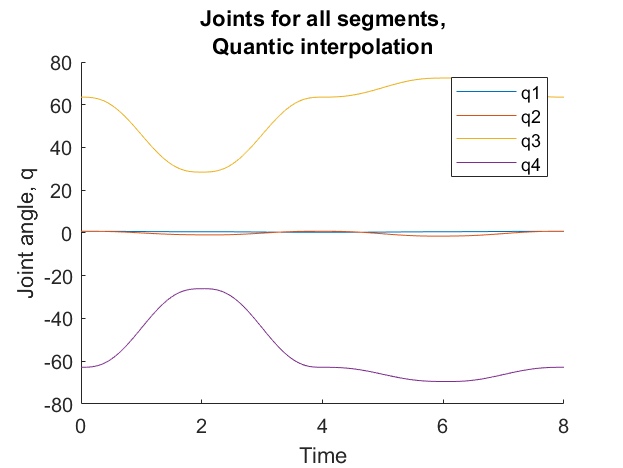

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments,","Quantic interpolation"])
legend(["q1","q2","q3","q4"])

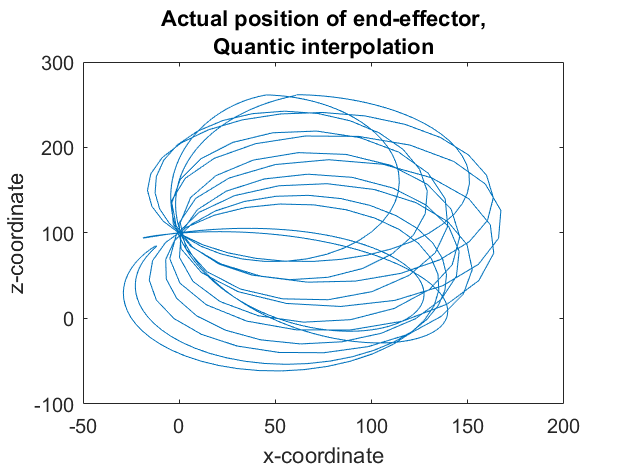



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,","Quantic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## Cubic interpolation


A = getConstantCubic(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A =     0.7389    0.4700   55.2415  -54.1555
   -0.0468   -0.4048   -8.3033    8.7089
   -0.0079   -0.0831   -1.3787    1.4671
    0.0026    0.0199    0.4622   -0.4812


B = getConstantCubic(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B =     0.5252   -0.4087   36.7612  -34.7965
   -0.0636    0.3052    8.3377   -8.6109
   -0.0103    0.0924    1.3833   -1.4860
    0.0035   -0.0257   -0.4590    0.4855


C = getConstantCubic(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C =     0.3663    0.2742   65.6129  -64.3394
    0.0641   -0.5710    2.1766   -1.6044
    0.0172   -0.0686    0.3481   -0.2711
   -0.0025    0.0308   -0.1140    0.0845


D = getConstantCubic(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D =     0.6163   -0.9399   70.3438  -67.8562
    0.0868    0.6036   -2.0348    1.4813
   -0.0051    0.0694   -0.3792    0.2938
   -0.0016   -0.0283    0.1197   -0.0901


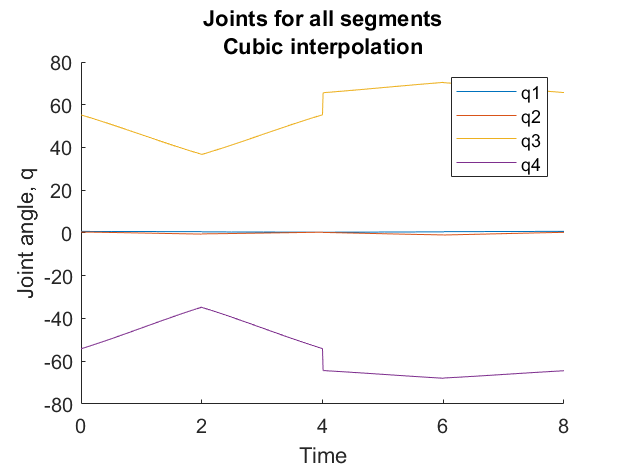

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Cubic interpolation"])
legend(["q1","q2","q3","q4"])

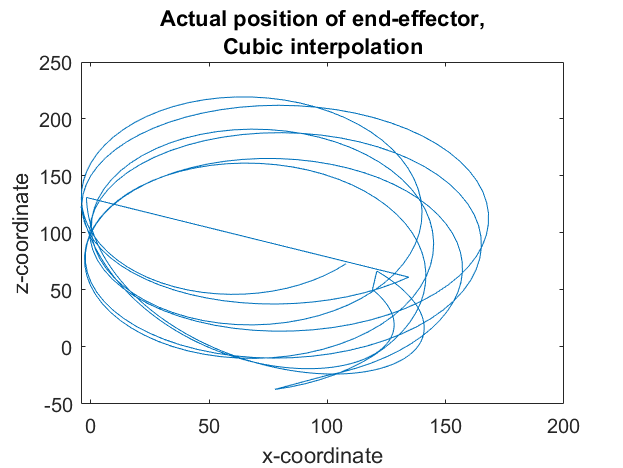



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Cubic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

## double the knot points

% calculate the approrate speeds at pi/4, 3pi/4 and 5pi/4 and 7pi/4
w = 4*sin(pi/2)/32e-3;
vz = w*cos(pi/4)*32e-3;
vy = w*sin(pi/4)*32e-3;


q0A = [t1(5),t2(5),t3(5),t4(5)]';
q0B = [t1(15),t2(15),t3(15),t4(15)]';
q0C = [t1(23),t2(23),t3(23),t4(23)]';
q0D = [t1(33),t2(33),t3(33),t4(33)]';

V0A = [0;-vy;vz;0;0;0];
V0B = [0;-vy;-vz;0;0;0];
V0C = [0;vy;-vz;0;0;0];
V0D = [0;vy;vz;0;0;0];

[T01,T12,T23,T34,T35] = T_finder(t1(5),t2(5),t3(5),t4(5));
J0A = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(15),t2(15),t3(15),t4(15));
J0B = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(23),t2(23),t3(23),t4(23));
J0C = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(33),t2(33),t3(33),t4(33));
J0D = Jacob(T01,T12,T23,T34);

q0A_dot = J0A'*inv(J0A*J0A')*V0A;

q0B_dot = J0B'*inv(J0B*J0B')*V0B;

q0C_dot = J0C'*inv(J0C*J0C')*V0C;

q0D_dot = J0D'*inv(J0D*J0D')*V0D;



A0 = getConstant(tIN,tOUT,q0,q0A,q0_dot,q0A_dot,ain,aout)

A0 =     0.7854    0.8279   63.5604  -62.8176
    0.0000         0    0.0000   -0.0000
         0         0         0         0
   -0.0396    1.1475  -21.4893   20.4523
    0.0284   -0.8647   16.1076  -15.3396
   -0.0055    0.1734   -3.2206    3.0680


A = getConstant(tIN,tOUT,q0A,qA,q0A_dot,qA_dot,ain,aout)

A =     0.7448    1.7196   46.3092  -46.4580
   -0.0110   -0.0329   -0.0748   -0.0029
         0         0         0         0
   -0.1785   -3.0011  -22.2138   25.3181
    0.1351    2.2315   16.6775  -18.9648
   -0.0272   -0.4444   -3.3372    3.7906


B0 = getConstant(tIN,tOUT,qA,q0B,qA_dot,q0B_dot,ain,aout)

B0 =     0.5880   -0.8707   28.4985  -26.0569
   -0.0010   -0.1875    0.0625    0.1875
         0         0         0         0
   -0.2706    3.4642   22.1722  -25.7412
    0.2062   -2.5678  -16.6373   19.2773
   -0.0416    0.5105    3.3283   -3.8526


B = getConstant(tIN,tOUT,q0B,qB,q0B_dot,qB_dot,ain,aout)

B =     0.3902    1.7196   46.3092  -46.4580
    0.0249    0.0550   -0.0026   -0.0413
         0         0         0         0
   -0.1229   -1.1325   21.4557  -20.3399
    0.0891    0.8344  -16.0775   15.2541
   -0.0175   -0.1654    3.2141   -3.0507


C0 = getConstant(tIN,tOUT,qB,q0C,qB_dot,q0C_dot,ain,aout)

C0 =     0.3218    0.8279   63.5604  -62.8176
   -0.0000   -0.0646    0.1122   -0.0476
         0         0         0         0
    0.2624    0.1652    9.5960   -9.4960
   -0.2189   -0.0360   -7.2086    7.0126
    0.0460   -0.0016    1.4429   -1.3916


C = getConstant(tIN,tOUT,q0C,qC,q0C_dot,qC_dot,ain,aout)

C =     0.3902    1.3935   71.3873  -71.2099
   -0.1768    0.6386    0.0193   -0.9231
         0         0         0         0
    0.4343   -4.6370    1.2002    3.7370
   -0.2938    3.4136   -0.8825   -2.7108
    0.0556   -0.6763    0.1747    0.5330


D0 = getConstant(tIN,tOUT,qC,q0D,qC_dot,q0D_dot,ain,aout)

D0 =     0.5880   -1.4498   72.4986  -69.4781
    0.0781    0.1250    0.1602   -0.1875
         0         0         0         0
   -0.0648    3.4749   -1.8754   -1.6576
    0.0568   -2.6353    1.4172    1.2384
   -0.0122    0.5300   -0.2845   -0.2472


D = getConstant(tIN,tOUT,q0D,qD,q0D_dot,qD_dot,ain,aout)

D =     0.7448    1.3935   71.3873  -71.2099
    0.1436   -0.1083    0.2459   -0.2260
         0         0         0         0
   -0.1648   -0.5445  -10.1524   10.8294
    0.1056    0.4219    7.5836   -8.0938
   -0.0193   -0.0857   -1.5136    1.6159


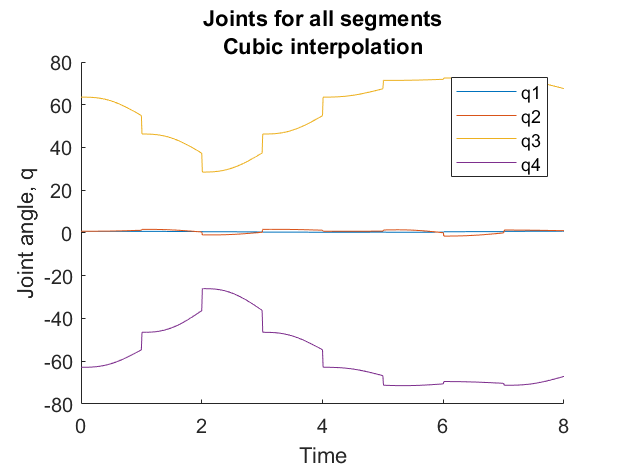


t = 0:0.01:1;
q10A = A0(1,1) + A0(2,1).*t + A0(3,1).*t.^2 + A0(4,1).*t.^3 + A0(5,1).*t.^4 + A0(6,1).*t.^5;
q20A = A0(1,2) + A0(2,2).*t + A0(3,2).*t.^2 + A0(4,2).*t.^3 + A0(5,2).*t.^4 + A0(6,2).*t.^5;
q30A = A0(1,3) + A0(2,3).*t + A0(3,3).*t.^2 + A0(4,3).*t.^3 + A0(5,3).*t.^4 + A0(6,3).*t.^5;
q40A = A0(1,4) + A0(2,4).*t + A0(3,4).*t.^2 + A0(4,4).*t.^3 + A0(5,4).*t.^4 + A0(6,4).*t.^5;

q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q10B = B0(1,1) + B0(2,1).*t + B0(3,1).*t.^2 + B0(4,1).*t.^3 + B0(5,1).*t.^4 + B0(6,1).*t.^5;
q20B = B0(1,2) + B0(2,2).*t + B0(3,2).*t.^2 + B0(4,2).*t.^3 + B0(5,2).*t.^4 + B0(6,2).*t.^5;
q30B = B0(1,3) + B0(2,3).*t + B0(3,3).*t.^2 + B0(4,3).*t.^3 + B0(5,3).*t.^4 + B0(6,3).*t.^5;
q40B = B0(1,4) + B0(2,4).*t + B0(3,4).*t.^2 + B0(4,4).*t.^3 + B0(5,4).*t.^4 + B0(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q10C = C0(1,1) + C0(2,1).*t + C0(3,1).*t.^2 + C0(4,1).*t.^3 + C0(5,1).*t.^4 + C0(6,1).*t.^5;
q20C = C0(1,2) + C0(2,2).*t + C0(3,2).*t.^2 + C0(4,2).*t.^3 + C0(5,2).*t.^4 + C0(6,2).*t.^5;
q30C = C0(1,3) + C0(2,3).*t + C0(3,3).*t.^2 + C0(4,3).*t.^3 + C0(5,3).*t.^4 + C0(6,3).*t.^5;
q40C = C0(1,4) + C0(2,4).*t + C0(3,4).*t.^2 + C0(4,4).*t.^3 + C0(5,4).*t.^4 + C0(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q10D = D0(1,1) + D0(2,1).*t + D0(3,1).*t.^2 + D0(4,1).*t.^3 + D0(5,1).*t.^4 + D0(6,1).*t.^5;
q20D = D0(1,2) + D0(2,2).*t + D0(3,2).*t.^2 + D0(4,2).*t.^3 + D0(5,2).*t.^4 + D0(6,2).*t.^5;
q30D = D0(1,3) + D0(2,3).*t + D0(3,3).*t.^2 + D0(4,3).*t.^3 + D0(5,3).*t.^4 + D0(6,3).*t.^5;
q40D = D0(1,4) + D0(2,4).*t + D0(3,4).*t.^2 + D0(4,4).*t.^3 + D0(5,4).*t.^4 + D0(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

q1 = [q10A, q1A(2:end), q10B(2:end), q1B(2:end), q10C(2:end), q1C(2:end), q10D(2:end), q1D(2:end)];
q2 = [q20A, q2A(2:end), q20B(2:end), q2B(2:end), q20C(2:end), q2C(2:end), q20D(2:end), q2D(2:end)];
q3 = [q30A, q3A(2:end), q30B(2:end), q3B(2:end), q30C(2:end), q3C(2:end), q30D(2:end), q3D(2:end)];
q4 = [q40A, q4A(2:end), q40B(2:end), q4B(2:end), q40C(2:end), q4C(2:end), q40D(2:end), q4D(2:end)];

t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title(["Joints for all segments","Cubic interpolation"])
legend(["q1","q2","q3","q4"])

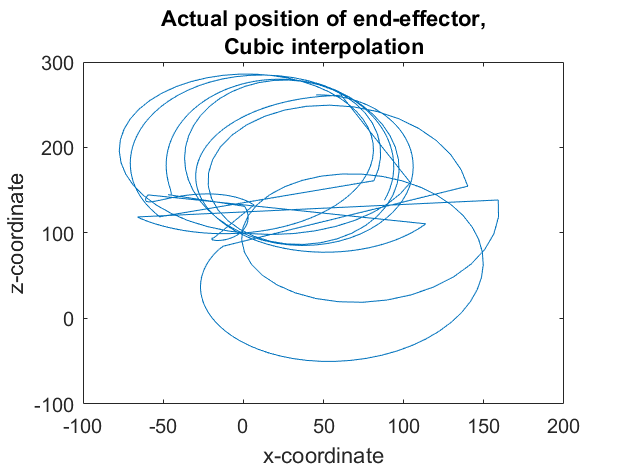



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title(["Actual position of end-effector,", "Cubic interpolation"])
xlabel("x-coordinate")
ylabel("z-coordinate")

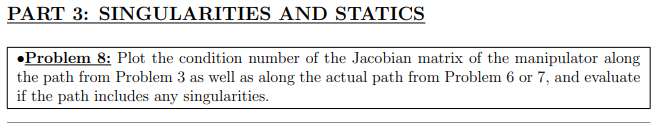


k=zeros(1,length(t1))

k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    J = [J(1:3,:);J(6,:)] ;% Remove rows that we do not wish to control
    k(i) = norm(inv(J))*norm(J); % calculate the condition number
end

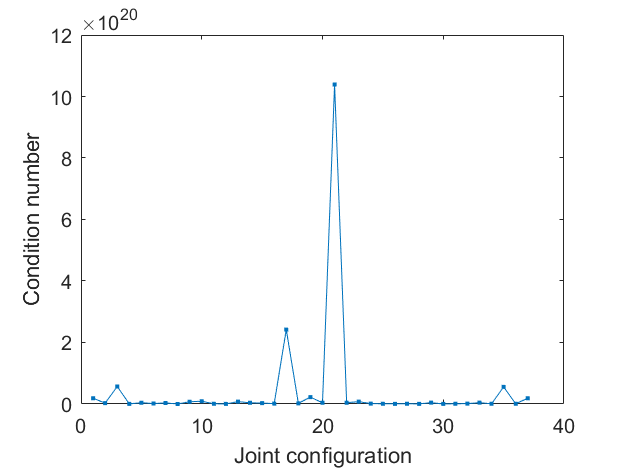

figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')

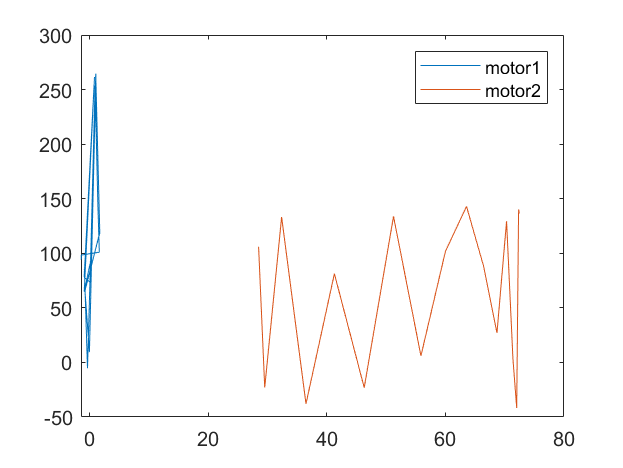

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);
end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])


disp("Motor 4 is omitted here as the torques are smaller than")

Motor 4 is omitted here as the torques are smaller than